## Rotated EOFs (varimax)

% Be sure you've run demo_1_cac_sst_eofs to compute the EOFs

colsst = cmocean('curl')

colsst =     0.0823    0.1149    0.2648
    0.0840    0.1231    0.2690
    0.0858    0.1312    0.2732
    0.0875    0.1391    0.2775
    0.0892    0.1469    0.2818
    0.0909    0.1546    0.2861
    0.0926    0.1622    0.2905
    0.0942    0.1697    0.2949
    0.0958    0.1772    0.2994
    0.0973    0.1846    0.3039



% Retain only the signifcant EOFs because it makes no sense to try to apply
% physical interpretation to modes we have determined have no statistical
% significance.
K = 1:4;
Ut = U(:,K);
A = S*V';
At = A(K,:);

% Approximate data reconstruction for K modes is:
Dt = Ut*At;

% Notice that the Ut and At show that the EOF loadings are orthogonal
disp('EOF loading pattern correlations')

EOF loading pattern correlations


Ut'*Ut

ans =     1.0000   -0.0000   -0.0000   -0.0000
   -0.0000    1.0000   -0.0000   -0.0000
   -0.0000   -0.0000    1.0000   -0.0000
   -0.0000   -0.0000   -0.0000    1.0000


disp(' ')


% ... and the amplitude time series are uncorrelated:
disp('EOF time series correlations')

EOF time series correlations


At*At'

ans = 	1.0e+04 *

    2.4168    0.0000   -0.0000    0.0000
    0.0000    0.6572   -0.0000   -0.0000
   -0.0000   -0.0000    0.3430   -0.0000
    0.0000   -0.0000   -0.0000    0.2719



% compare to S^2
disp('S^2')

S^2


S(K,K).^2

ans = 	1.0e+04 *

    2.4168         0         0         0
         0    0.6572         0         0
         0         0    0.3430         0
         0         0         0    0.2719


### Compute the varimax rotation of Ut

[Ur,R] = varimax_kaplan(Ut);

% The rotated matrix is Ur = Ut*R
% Check:
range(Ur-Ut*R)

ans =      0
     0



% The new loadings (the columns of Un) are still orthogonal. Check:
disp('The new loadings (the columns of Un) are still orthogonal. Check:')

The new loadings (the columns of Un) are still orthogonal. Check:


Ur'*Ur

ans =     1.0000    0.0000    0.0000    0.0000
    0.0000    1.0000    0.0000    0.0000
    0.0000    0.0000    1.0000    0.0000
    0.0000    0.0000    0.0000    1.0000



% The (filtered) data matrix expansion can be written:
% Dt = Ut*R*inv(R)*At
% so we can write this as Dt = Ur*Ar with Ar = inv(R)*At;
Ar = inv(R)*At;

### Compare the loading patterns

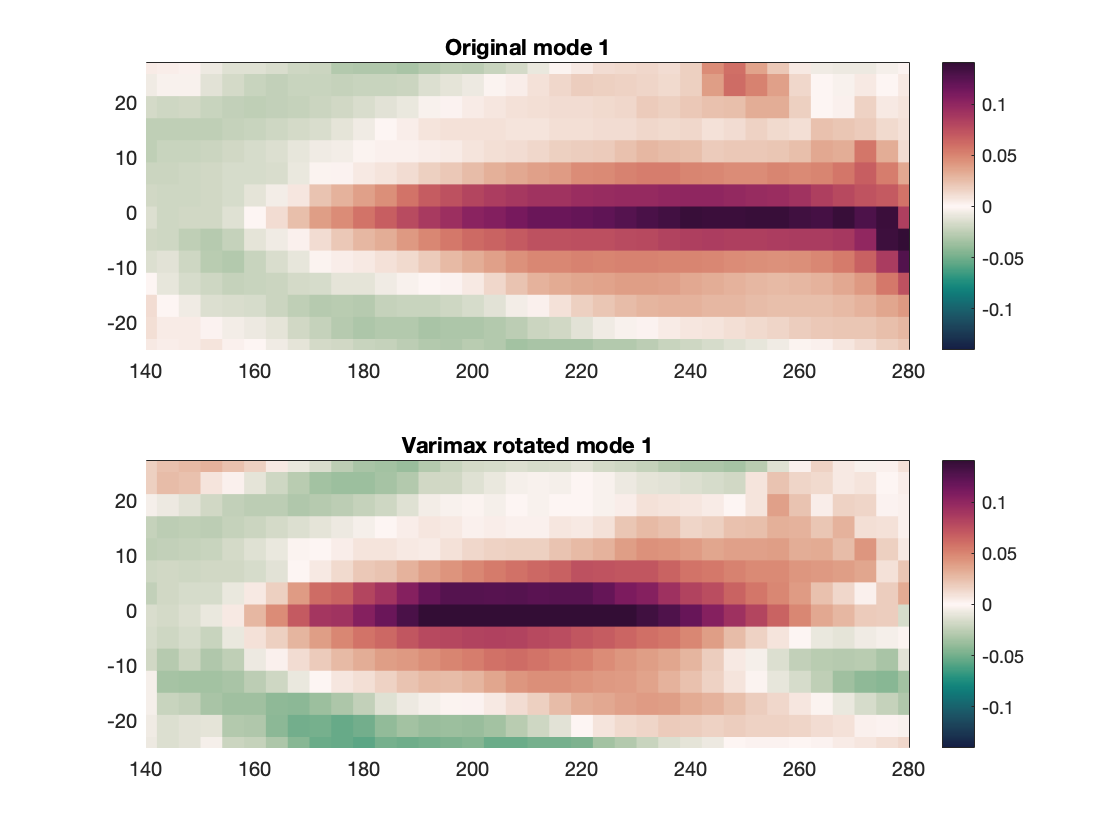

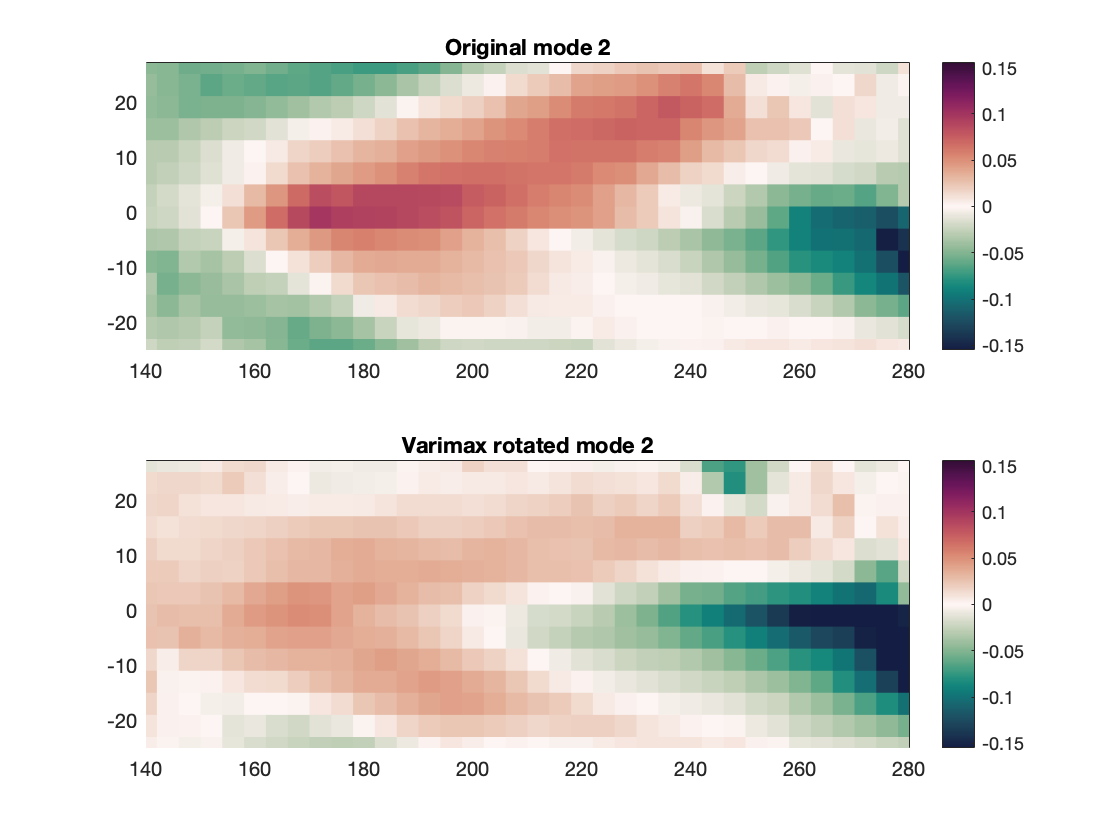

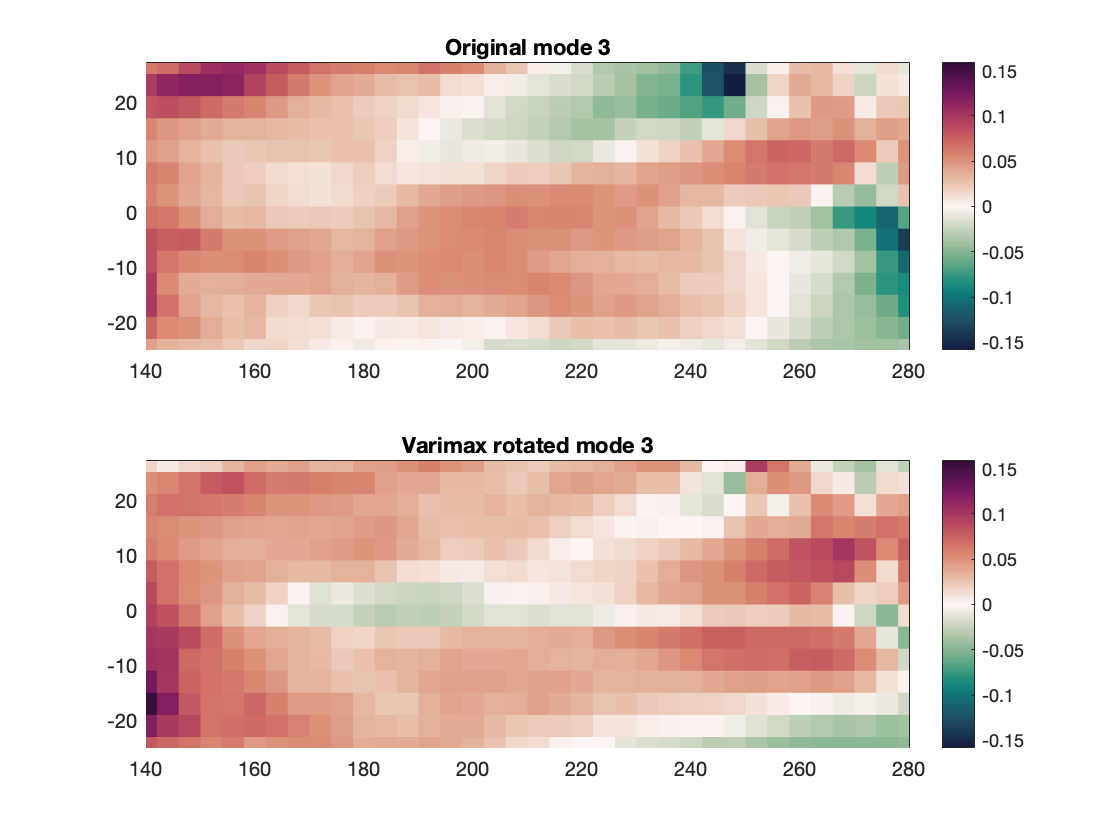

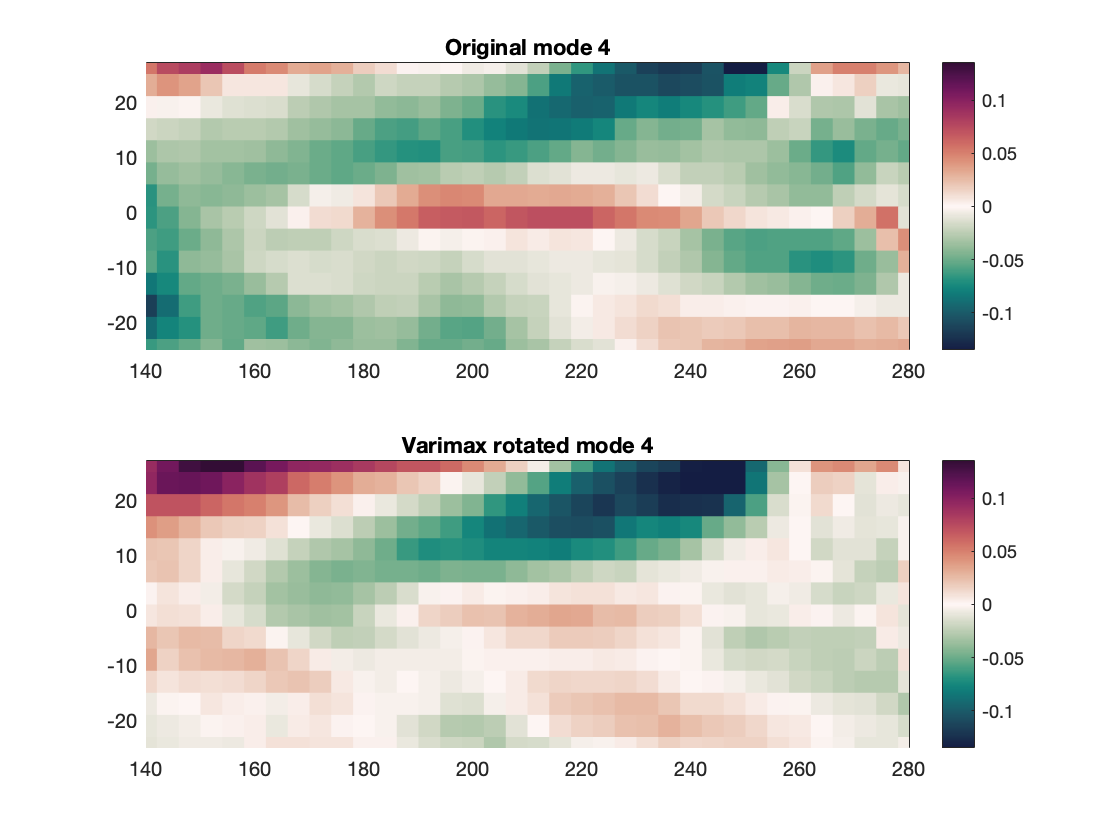

for m=1:max(K)
  figure
  colormap(colsst)
  subplot(211)
  pcolorjw(lon,lat,reshape(U(:,m),[nlats nlons]))
  caxis(max(abs(caxis))*[-1 1])
  cax = caxis; colorbar
  title(['Original mode ' int2str(m)])
  subplot(212)
  pcolorjw(lon,lat,reshape(Ur(:,m),[nlats nlons]))
  caxis(cax); colorbar
  title(['Varimax rotated mode ' int2str(m)])
end

### Compare %-variance explained for each mode

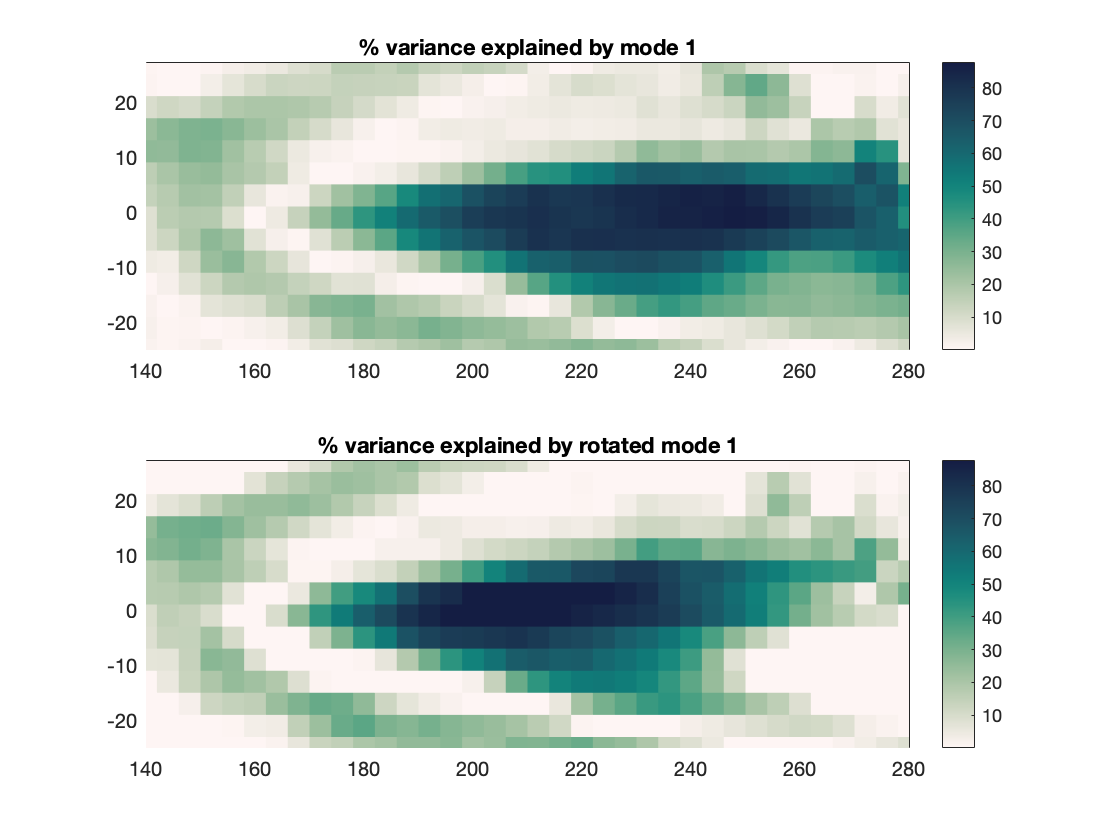

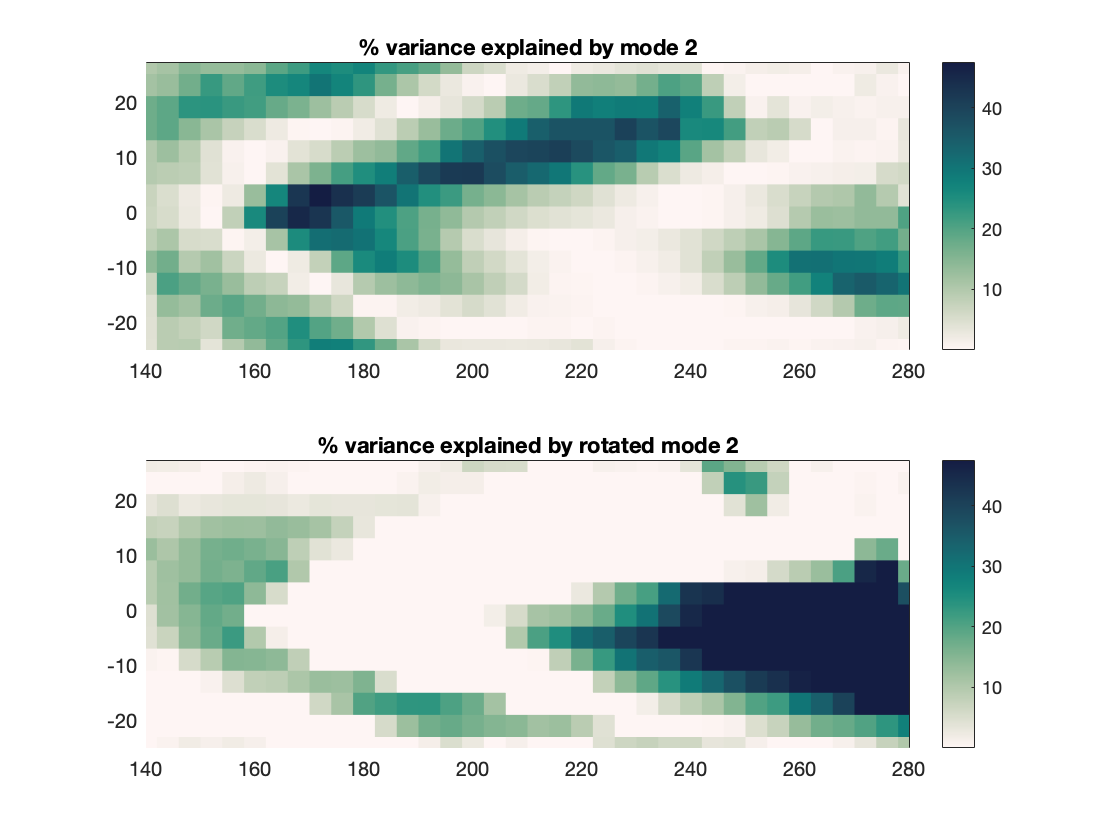

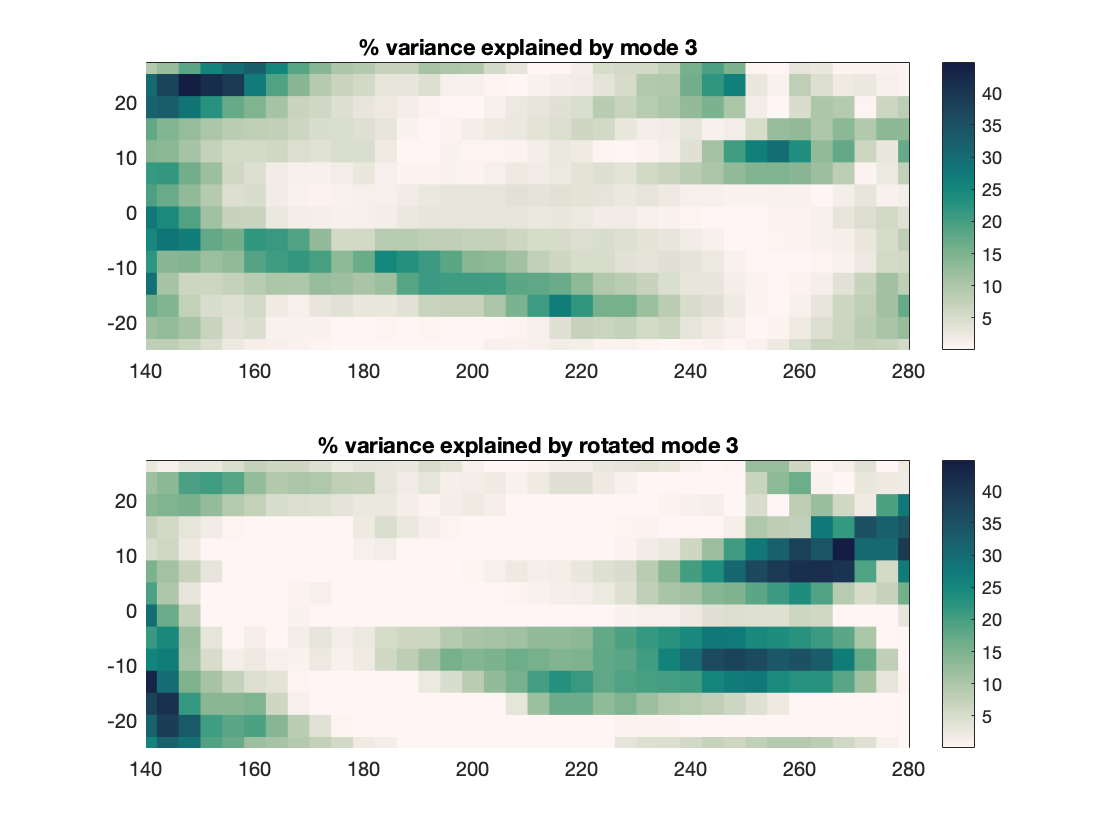

for m=1:3
  Dt = Ut(:,m)*At(m,:);
  Dr = Ur(:,m)*Ar(m,:);
  tmp = Dt-D;
  skt = 1-diag(tmp*tmp')./diag(D*D');
  tmp = Dr-D;
  skr = 1-diag(tmp*tmp')./diag(D*D');
  figure
  cmocean('tempo')
  hax(1)=subplot(211);
  pcolorjw(lon,lat,reshape(100*skt,[nlats nlons]));
  cax = caxis; colorbar
  title(['% variance explained by mode ' int2str(m)])
  hax(2)=subplot(212);
  pcolorjw(lon,lat,reshape(100*skr,[nlats nlons]));
  caxis(cax); colorbar
  title(['% variance explained by rotated mode ' int2str(m)])
  linkaxes(hax);
end

### Compare the amplitude time series

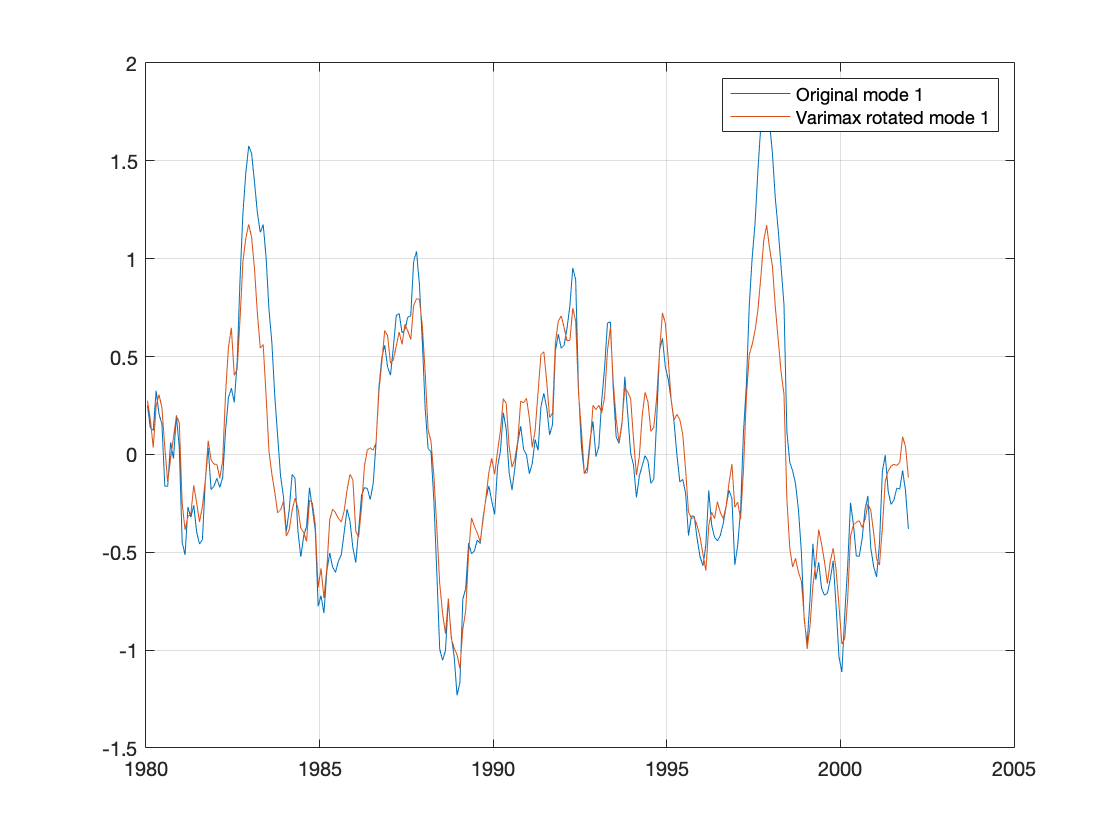

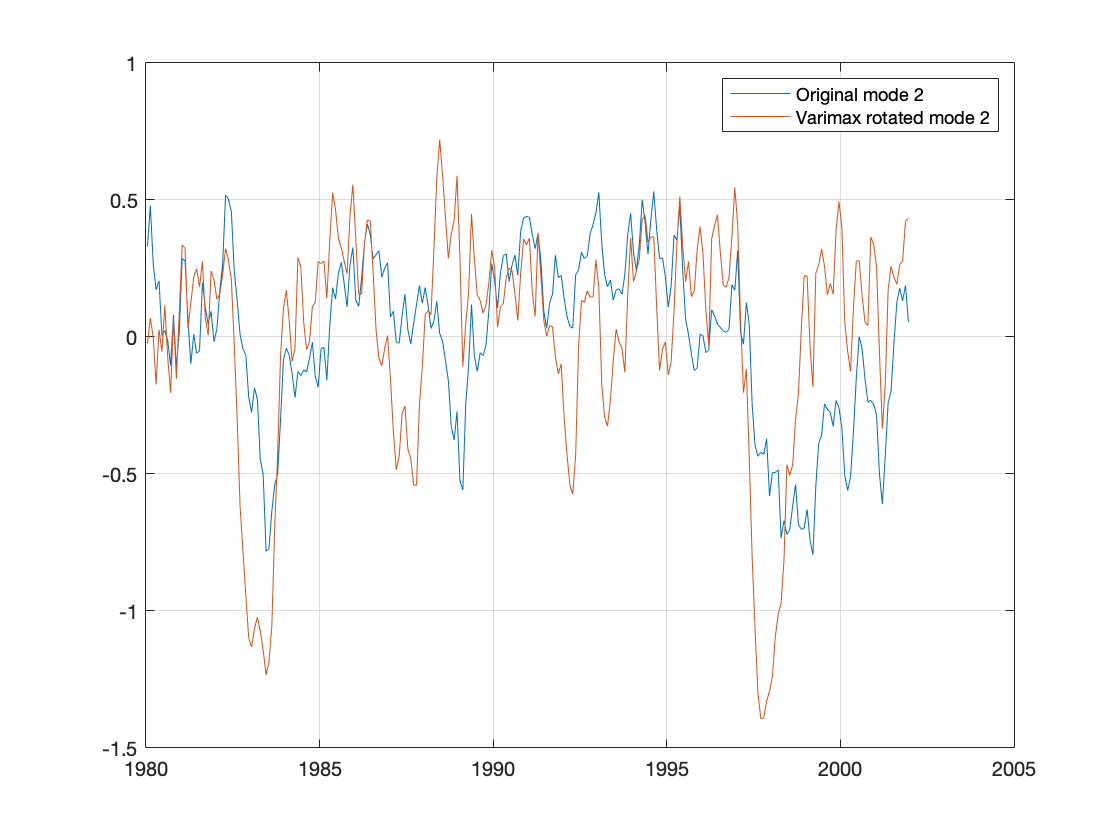

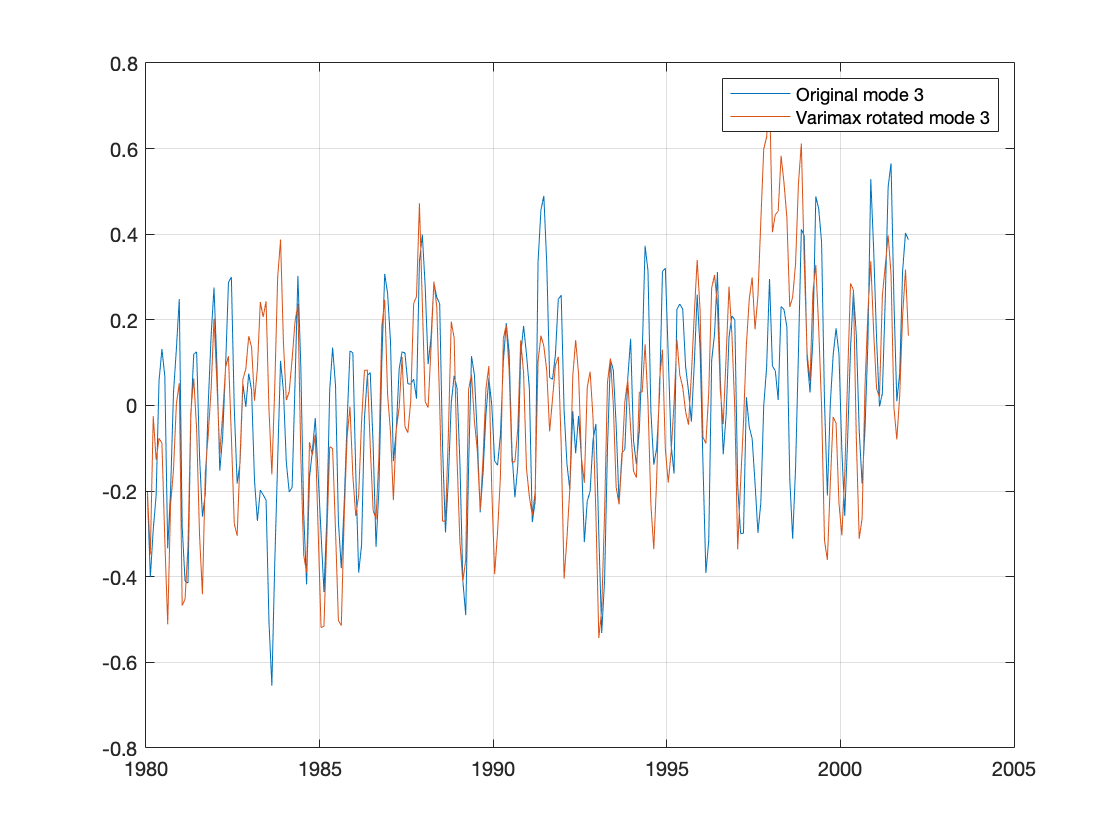

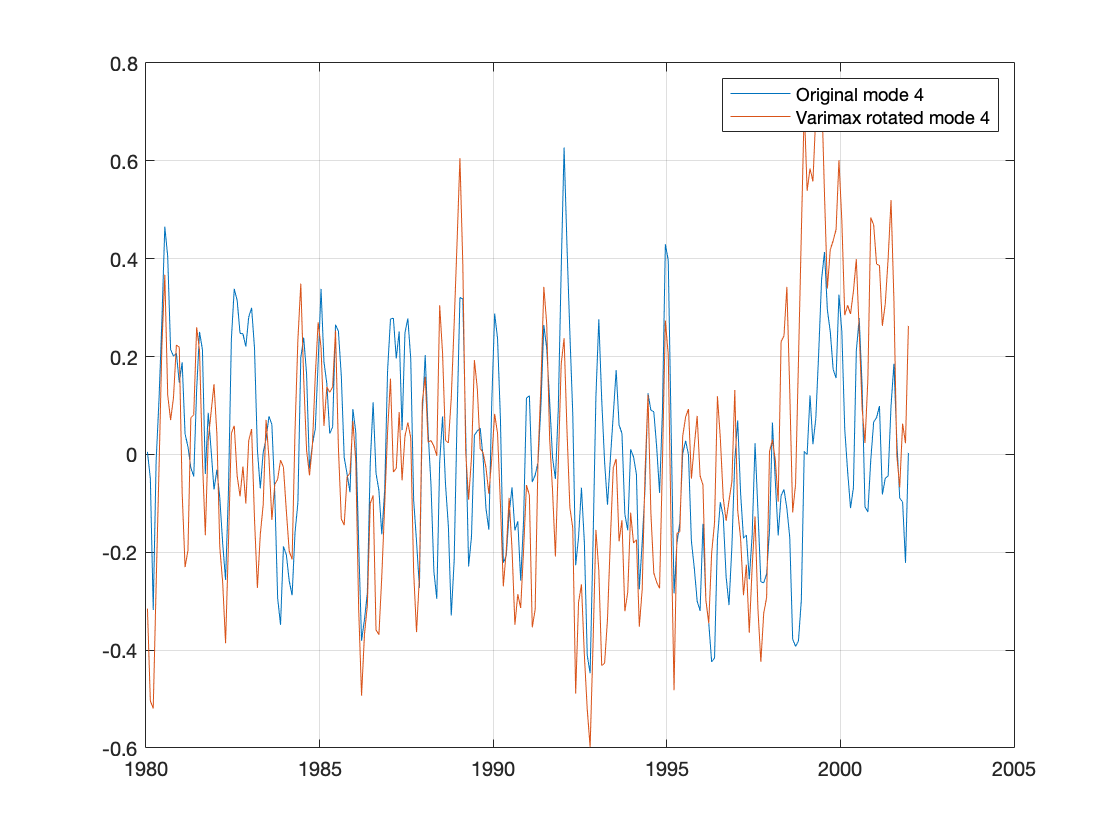

N = length(year);
for m=1:max(K)
  figure
  plot(year,At(m,:)/sqrt(N),year,Ar(m,:)/sqrt(N))
  legend(['Original mode ' int2str(m)],...
    ['Varimax rotated mode ' int2str(m)])
  grid on
end


% The total variance of the data is retained, but is distributed differently
% among the modes and has lost the property of maximizing the variance
% explained in the lowest mode, i.e. variance of rotated mode 1 is always
% less than unrotated.
tS = trace(S*S');
diag(At*At')/tS

ans =     0.4179
    0.1136
    0.0593
    0.0470


diag(Ar*Ar')/tS

ans =     0.2732
    0.2185
    0.0672
    0.0789


### The amplitude time series are correlated

% Compare
At*At'

ans = 	1.0e+04 *

    2.4168    0.0000   -0.0000    0.0000
    0.0000    0.6572   -0.0000   -0.0000
   -0.0000   -0.0000    0.3430   -0.0000
    0.0000   -0.0000   -0.0000    0.2719


Ar*At'

ans = 	1.0e+04 *

    1.8129    0.3217    0.1233    0.0712
   -1.4845    0.4363    0.1448   -0.0167
    0.3696   -0.2096    0.2137   -0.1897
   -0.4629   -0.3068    0.1892    0.1806


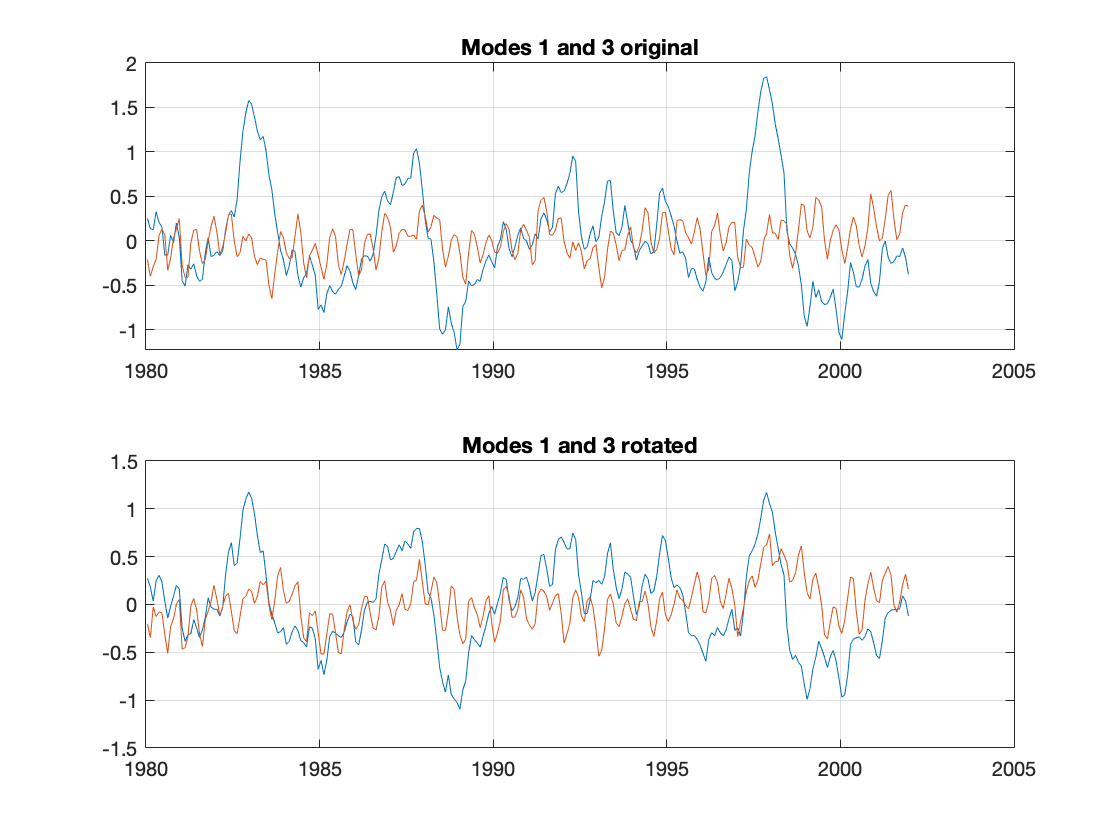


figure
subplot(211)
plot(year,At(1,:)/sqrt(N),year,At(3,:)/sqrt(N))
title('Modes 1 and 3 original')
grid on
subplot(212)
plot(year,Ar(1,:)/sqrt(N),year,Ar(3,:)/sqrt(N))
title('Modes 1 and 3 rotated')
grid on

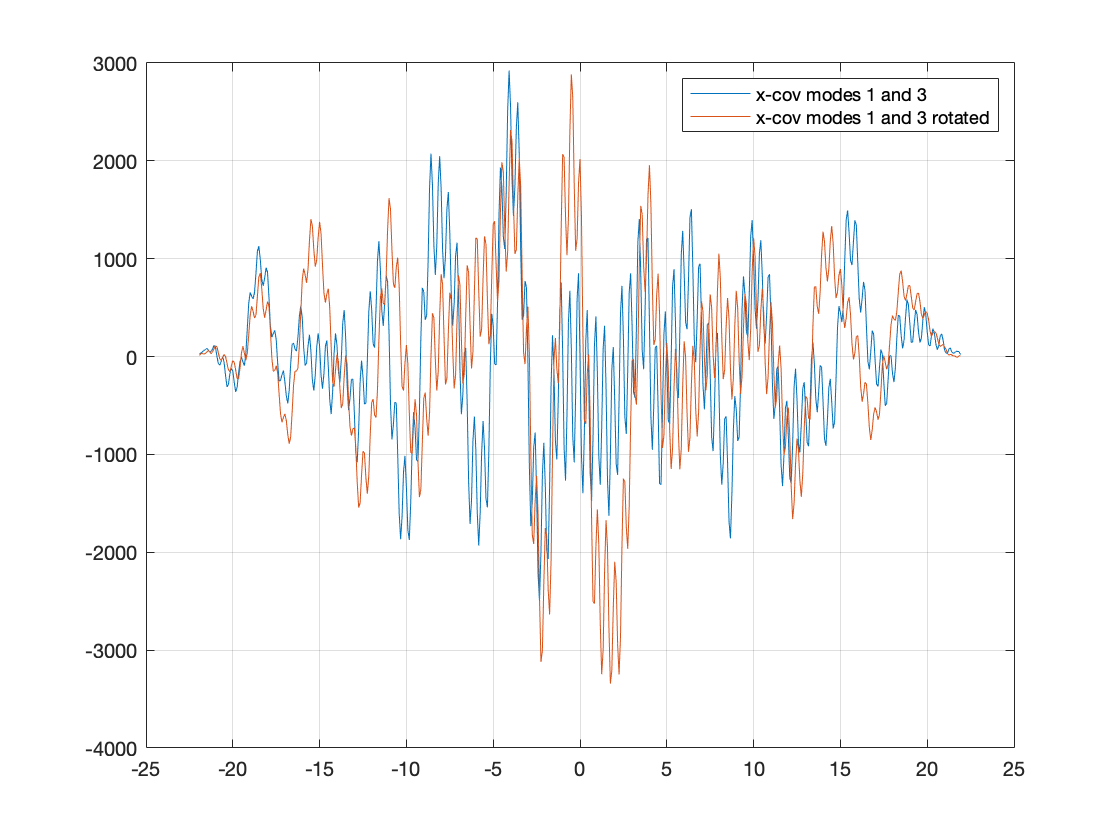


figure
[xct,~] = xcov(At(1,:),At(3,:));
[xcr,lags] = xcov(Ar(1,:),Ar(3,:));
plot(lags/12,xct,lags/12,xcr)
grid on
legend('x-cov modes 1 and 3 ','x-cov modes 1 and 3 rotated')

disp('peak shifted toward left implies mode 1 leads mode 3')

peak shifted toward left implies mode 1 leads mode 3


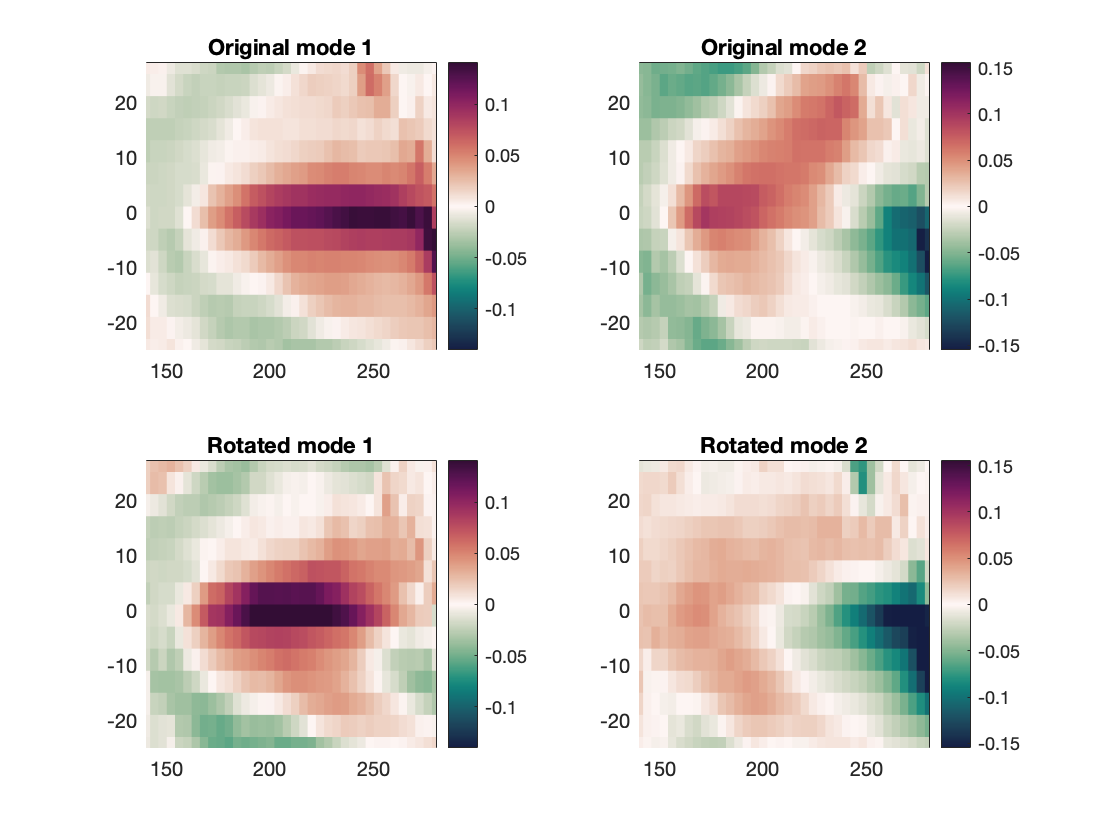

figure
colormap(colsst)
subplot(221)
m=1;
pcolorjw(lon,lat,reshape(Ut(:,m),[nlats nlons]))
caxis(max(abs(caxis))*[-1 1])
cax = caxis; colorbar
title(['Original mode ' int2str(m)])

subplot(223)
m=1;
pcolorjw(lon,lat,reshape(Ur(:,m),[nlats nlons]))
caxis(cax); colorbar
title(['Rotated mode ' int2str(m)])

subplot(222)
m=2;
pcolorjw(lon,lat,reshape(Ut(:,m),[nlats nlons]))
caxis(max(abs(caxis))*[-1 1])
cax = caxis; colorbar
title(['Original mode ' int2str(m)])

subplot(224)
m=2;
pcolorjw(lon,lat,reshape(Ur(:,m),[nlats nlons]))
caxis(cax); colorbar
title(['Rotated mode ' int2str(m)])

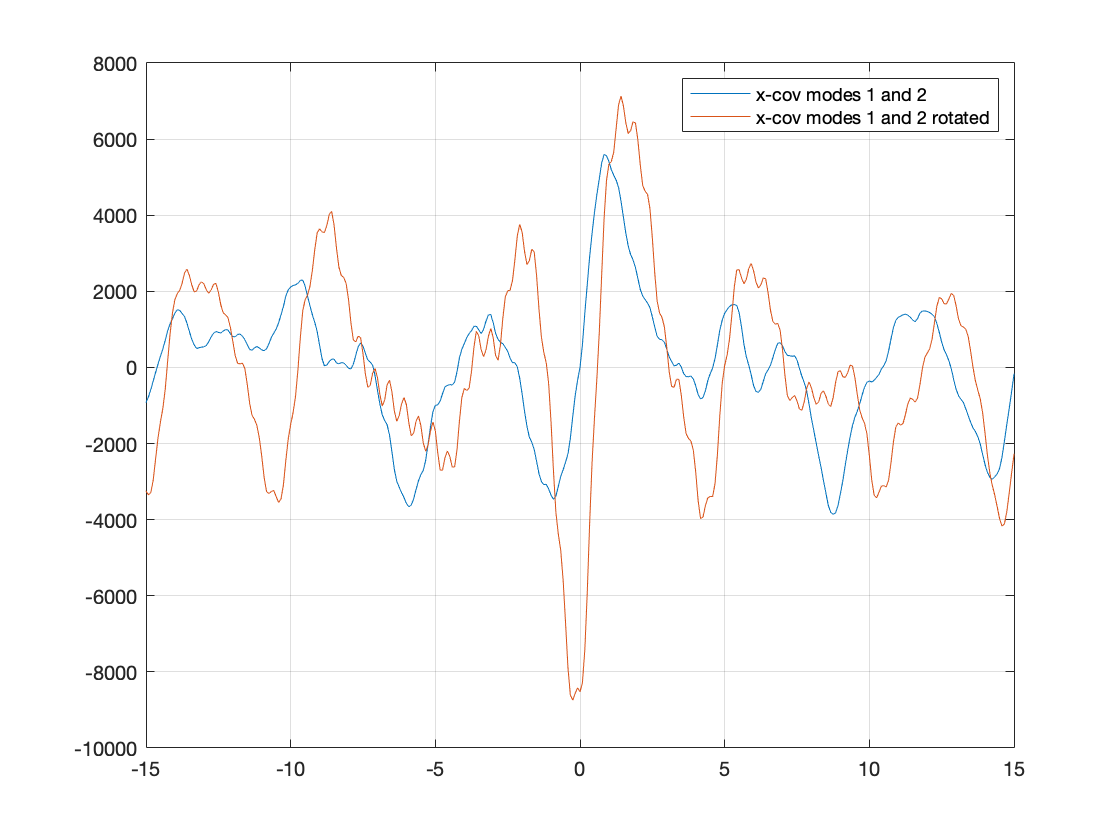


figure
[xcr,~] = xcov(Ar(1,:),Ar(2,:));
[xct,lags] = xcov(At(1,:),At(2,:));
plot(lags/12,xct,lags/12,xcr)
set(gca,'xlim',[-15 15])
grid on
legend('x-cov modes 1 and 2 ','x-cov modes 1 and 2 rotated')